%Note always wrap the diffence of the angles, which is being supplied to
%the controller error.
clear;
clc;

g = 9.81; %m/s^2
va = 15; %m/s
phiMax = 45*pi/180; %radians
psiDotMax = g*tan(phiMax)/va %radians/sec

psiDotMax = 0.6540

kMaxu = psiDotMax/va %m^-1

kMaxu = 0.0436

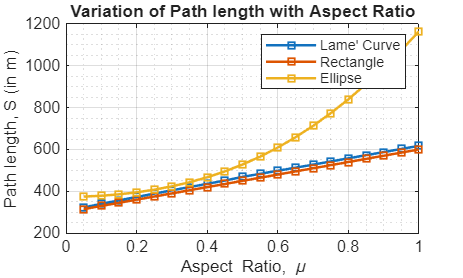


%Variation in path lengths with different aspect ratios
l = 75;
mu = 0.05:0.05:1;
m = l*mu;
sz = size(mu);

lvals = zeros([6, sz(2)]);
elvals = zeros([6, sz(2)]);
lvals(1:2,:) = [l*ones([1,sz(2)]);m];
elvals(1:2,:) = [l*ones([1,sz(2)]);m];

i = 1;
while i <= sz(2)
    [lvals(3,i),lvals(4,i),lvals(5,i),lvals(6,i)] = lameVals(lvals(1,i),lvals(2,i), kMaxu);
    [elvals(3,i),elvals(4,i),elvals(5,i),elvals(6,i)] = ellipseVals(elvals(1,i),elvals(2,i), kMaxu);
    i = i + 1;
end

figure;
plot(mu, lvals(6,:),marker="square",markersize=5, LineWidth=1.5);
hold on;
grid on; grid minor;
plot(mu, 4*(lvals(1,:) + lvals(2,:)),marker="square",markersize=5, linewidth=1.5);
plot(mu, elvals(6,:), marker="square", markersize = 5, linewidth = 1.5);
legend("Lame' Curve", "Rectangle", "Ellipse");
xlabel("Aspect Ratio, \mu");
ylabel("Path length, S (in m)");
title("Variation of Path length with Aspect Ratio");
hold off;

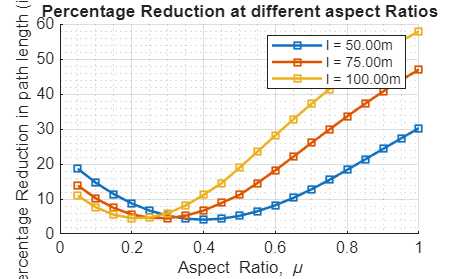


%percentage reduction in path length with the Aspect Ratio for different
%l values
ls = [50, 75, 100];

sz = size(ls);
plt = gobjects(1, sz(2));
labels = cell(1, sz(2));

sz = size(mu);
lvals = zeros([6, sz(2)]);
elvals = zeros([6, sz(2)]);

j = 1;
figure;
hold on;
grid on; grid minor;
for l = ls
    m = l*mu;

    lvals(1:2,:) = [l*ones([1,sz(2)]);m];
    elvals(1:2,:) = [l*ones([1,sz(2)]);m];
    
    i = 1;
    while i <= sz(2)
        [lvals(3,i),lvals(4,i),lvals(5,i),lvals(6,i)] = lameVals(lvals(1,i),lvals(2,i), kMaxu);
        [elvals(3,i),elvals(4,i),elvals(5,i),elvals(6,i)] = ellipseVals(elvals(1,i),elvals(2,i), kMaxu);
        i = i + 1;
    end
    
    pered = (elvals(6,:) - lvals(6,:))*100 ./ elvals(6,:);
    plt(j) = plot(mu, pered, linewidth = 1.5, marker= "square", markersize = 5);
    labels{j} = sprintf("l = %0.2fm", l);

    j = j + 1;
end

legend(plt,labels);
title("Percentage Reduction at different aspect Ratios");
xlabel("Aspect Ratio, \mu");
ylabel("Percentage Reduction in path length (in %)");
hold off;

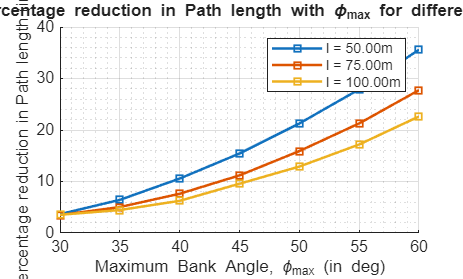


%percentage reduction in path length with bank angle limit phiMax (φ_max)
%for different values of l
ls = [50, 75, 100];
m = 37.5;
sz1 = size(ls);

phiMax = (30:5:60)*pi/180;
kMaxu = g*tan(phiMax) ./ va^2;
sz2 = size(phiMax);

lvals = zeros([7, sz2(2)]);
elvals = zeros([7, sz2(2)]);

plt = gobjects(1, sz1(2));
labels = cell(1, sz1(2));

figure;
hold on;
grid on; grid minor;

j = 1;
for l = ls
    lvals(1,:) = ones([1, sz2(2)])*l;
    lvals(2,:) = ones([1, sz2(2)])*m;
    lvals(3,:) = kMaxu;

    elvals(1:3,:) = lvals(1:3, :);

    i = 1;
    while i <= sz2(2)
        [lvals(4,i),lvals(5,i),lvals(6,i),lvals(7,i)] = lameVals(l,m,kMaxu(i));
        [elvals(4,i),elvals(5,i),elvals(6,i),elvals(7,i)] = ellipseVals(l,m,kMaxu(i));

        i = i + 1;
    end
    
    pered = (elvals(7,:) - lvals(7,:))*100 ./ elvals(7,:);
    plt(j) = plot(phiMax*180./pi, pered, linewidth = 1.5, marker = "square", markersize = 5);
    labels{j} = sprintf("l = %0.2fm", l);

    j = j + 1;
end

legend(plt, labels);
title("Percentage reduction in Path length with \phi_m_a_x for different l's");
xlabel("Maximum Bank Angle, \phi_m_a_x (in deg)");
ylabel("Percentage reduction in Path length (in %)");
hold off;



function [n,a,b,S] = lameVals(l,m,kMaxu)
    narr = 2:0.05:10;
    sz = size(narr);
    perim = zeros([1, sz(2)]);
    an = zeros([1, sz(2)]);
    bn = zeros([1, sz(2)]);
    
    i = 1;
    while i < sz(2)
        F = @(a) (narr(i)-1)* m * a^narr(i) * (a^narr(i) - l^narr(i)) * l^(narr(i)-2) / (m^2 * l^(2*narr(i)-2) + (a^narr(i) - l^narr(i))^2)^(3/2) - kMaxu;

        a = fzero(F, l+5, optimset('Display','off'));
        if isnan(a)
            i = i+1;
            continue;
        end
        b = a*m/(a^narr(i) - l^narr(i))^(1/narr(i));

        perim(i) = peri(narr(i),a,b);
        an(i) = a;
        bn(i) = b;

        i = i + 1;
    end
        
        nonzero_indices = find(perim > 0);              % Indices where perim is non-zero
        [~, min_idx_rel] = min(perim(nonzero_indices)); % Relative index of min non-zero
        min_idx = nonzero_indices(min_idx_rel);         % Actual index in original array
        n = narr(min_idx);                             % Corresponding value in narr
        a = an(min_idx);
        b = bn(min_idx);
        S = perim(min_idx);
end

function [n,a,b,S] = ellipseVals(l,m,kMaxu)
    n = 2;
    if l >= m
        r = roots([1, -kMaxu*m^2, -l^2]);
        a = r(r > l);
        a = a(end);
        b = a*m/sqrt(a^2 - l^2);
    else
        r = roots([1, -l^2 * kMaxu, -m^2]);
        b = r(r > m);
        b = b(end);
        a = b*l/sqrt(b^2 - m^2);
    end
    S = peri(n,a,b);
end

function S = peri(n,a,b)
    x1 = a:-0.01:0;
    x2 = -0.01:-0.01:-a;
    x = [x1 x2 flip(x2(2:end)) flip(x1)];
    
    y1 = (b/a) * (a^n - x1.^n).^(1/n);
    y2 = (b/a) * (a^n - (-x2).^n).^(1/n);
    y = [y1 y2  flip(-y2(2:end)) flip(-y1)];

    dx = diff(x);
    dy = diff(y);
    S = sum(sqrt(dx.^2 + dy.^2));
end
